Companion software for "Volker Ziemann, *Physics and Finance, Springer, 2021*" ([https://link.springer.com/book/10.1007/978-3-030-63643-2](https://link.springer.com/book/10.1007/978-3-030-63643-2))

# Student's t-distribution and hypothesis testing (Section 7.5 and 7.6)

Volker Ziemann, 211129, CC-BY-SA-4.0

When determining fit-parameters from few data points $N$, measurement noise can 'conspire' to cause fit-parameters that deviate significantly from their 'true' value, where the latter is the value we would obtain with many data points. Student's t-distribution describes this excess probability of finding outliers. We emphasize that $t$ is the deviation of a fit-parameter from the true value, normalized to the empirically determined standard deviation, as defined in Equation 7.27.

The degree of freedom $\nu=N-q$ of a fit is excess of data points $N$ over the number of fit parameters $q$ and provides the redundancy to provide the increased reliability that a fit parameter is 'true'. After setting the value of $\nu$ with a slider, we define an anonymous function `tdist()` to encode the t-distibution from Equation 7.33, plot the t-distribution for $\nu$ degrees of freedom, and annotate the axes. Note that MATLAB also provides a built-in function `tpdf()` that can be used as a drop-in replacement for `tdist()`.

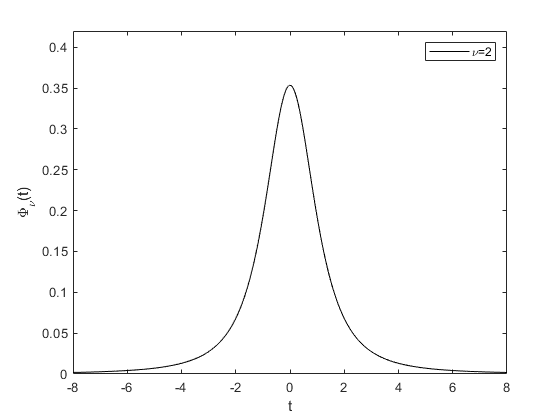

clear 
nu=2; % Slider to set the degrees of freedom nu
t=-8:0.01:8;
tdist=@(t,nu)(gamma(0.5*(nu+1))./(sqrt(pi*nu)*gamma(0.5*nu))) ...
  *(1+(t.^2./nu)).^(-0.5*(nu+1));   % eq. 7.33
plot(t,tdist(t,nu),'k');  % or tpdf(t,nu)
xlabel('t'); ylabel('\Phi_\nu(t)')
legend(['\nu=',num2str(nu)])
xlim([-8,8]); ylim([0,0.42])

We observe that for small $\nu$ the tails of the distribution are much more pronounced compared fto those with larger values of $\nu$. 

#### Confidence level

The interval around the central value (here $t=0$) that contains a certain percentage, say 90%, of the entire distribution is the 90%-percent confidence level. Here we see that this interval is much larger for smaller $\nu$, because the tails of the distribution are more pronounced. We therefore need to determine the value of $\hat t$ such that $\pm\hat t$ contains 90% of the distribution. 

In the following code segment we use a slider to set the desired confidence level and then use Equation 7.34 to calculate the probability $A(\hat t,\nu)$ that is contained in the interval of $\pm\hat t$. The plot shows$A(\hat t,\nu)$ as a function of $\hat t$ as a black line and the chosen confidence level as a red dashed line. The intersection of the black and red lines determines the value if $\hat t$ that defines the confidence interval.

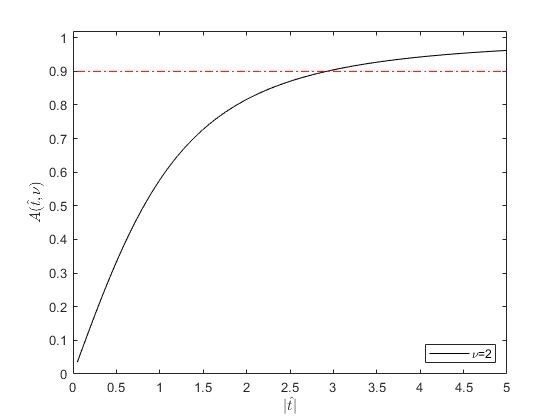

confidence_level=0.9; % Slider to set confidence_level
A=@(that,nu)1-betainc(nu./(nu+that.^2),nu/2,0.5); % eq.7.34
that=0.05:0.05:5;
plot(that,A(that,nu),'k',that,confidence_level*ones(size(that)),'r-.')
ylim([0,1.02])
xlabel('$|\hat t|$','interpreter','latex')
ylabel('$A(\hat t,\nu)$','interpreter','latex')
legend(['\nu=',num2str(nu)],'Location','SouthEast')

We observe that reducing the confidence level moves the intersection towards smaller values. Thus the confidence interval gets smaller, but the confidence in it is reduced.

#### Confidence interval

Finally, we work out how the confidence interval that corresponds to a chosen confidence level changes if we have more data points $N$ available which in turn increases the degrees of freedom $\nu$. We therefore find the intersection of $A(\hat t,\nu)$ and the confidence level for increasing values of $\nu$ and plot $\hat t$ as a function of $\nu$. Note that  we also show the value of $\nu$ selected with the slider on the top of thus script as a vertical red line. Again, the intersection of the curves occurs at the same value of $\hat t$ as in the previous plot.

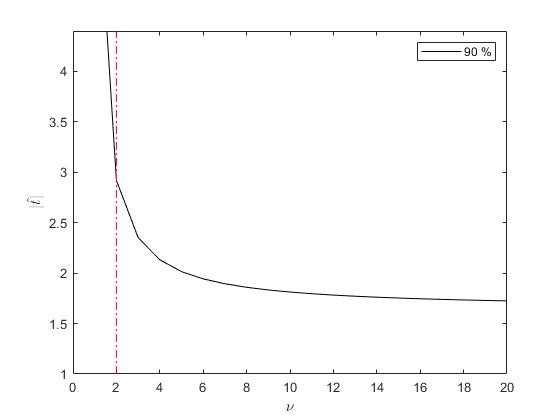

nuaxis=1:1:20;
data=zeros(length(nuaxis),1);
for k=1:length(nuaxis)
  q=@(t)A(t,nuaxis(k))-confidence_level;
  data(k,1)=fzero(q,[0,19]);
end
figure
plot(nuaxis,data(:,1),'k',[nu,nu],[1,4.4],'r-.')
ylim([1,4.4]); xlim([0,20])
xlabel('\nu'); ylabel('$|\hat t|$','interpreter','latex')
legend([num2str(100*confidence_level),' %'])

We observe that $\hat t$ decreases with increasing $\nu$ and levels off at $\hat t =2$, which is intuitively appealing, because increasing the degrees of freedom causes the t-distribution to approach a Gaussian, which contains 90% probability within two standard deviations. And, as mentioned in the first paragraph, $t$ is the deviation from the true value, measured in units of the standard deviation.

#### Hypothesis testing and p-value

We can turn the concept of confidence interval upside-down, which help us to decide whether a particular fit-parameter $x_j$ is actually needed in a fit. Conventionally, this is formulated by a *null-hypothesis*, which simply states "we make the hypothesis that $x_j$ is zero."  If we then can show that $x_j$ in our particular fit lies outside the 90% confidence interval it's rather probably that the fit parameter is different from zero and we say that the hypothesis is rejected at the 10% level. 

Moreover, assume that we calculate a $t-$value for $x_j$ in this particular fit, then the probability $p$ of finding an a value of $x_j$ that causes an even larger value of $t$ is called the p-value.